# ***Final Project Robotics and Control 2 ***

A.Y. 2023/2024 Course of Professor. A. Cenedese

Group 1: Adami Alessandro, Peron Davide, Vitetta Emanuele

clear all

**Useful Constants**

deg2rad=pi/180;
rad2deg=1/deg2rad;

**Butterworth derivative filter**

s = tf("s");
w_filter = 50;
[num_filter, den_filter]= tfdata((((2*pi*w_filter)^2)*s)/(s^2+2/sqrt(2)*2*pi*w_filter*s+(2*pi*w_filter)^2), 'v');

**Saturations**

v_sat=1;
w_sat=1.5; 
der_sat=1;

# *Rendez-vouz Problem*

In the following section we will provide our solution for Phase 1 namely the solution of the rendez-vous problem

We used an hybrid tecnique: since we don't have any real comunication between the robots or a master that decide the rendez-vous pose we use an hybrid tecnique to guarantee that for Phase 3 we can generate a trajecotry of radius at least 1m and away at least 0.5m from the walls of the room we are in Phase 3.

The first step will be to calculate the consensuns poste using consensus theory as wee saw during the lectures if this pose respect our desired conditions we will use it otherwise we will give as rendez-vous pose a position that satisfies the requirements

We will consider a square room with side 7m with one vertex on the origin and the rest on the first quadrant of the XY plane

Robots initial positions

%p1 = [0,4,pi];
%p2 = [2,0,pi];
%p3 = [4,4,pi];
p1 = [6,6,pi];
p2 = [6,1,pi/2];
p3 = [1,3,-pi/2];
p0 = [p1;p2;p3];

Definition of the P matrix

P =[0.5, 0.25, 0.25;
    0.25, 0.5, 0.25;
    0.25, 0.25, 0.5];

P_10= P^10 

P_10 =     0.3333    0.3333    0.3333
    0.3333    0.3333    0.3333
    0.3333    0.3333    0.3333


Calculating consensus pose

P_fin=P_10*p0;
p_fin=P_fin(1,:);

Checking if the pose is acceptable and changing the coordinates that do not respect the given condition

if(p_fin(1)<1.5)
    p_fin(1) = 1.5
end
if(p_fin(1)>5.5)
    p_fin(1) = 5.5
end
if(p_fin(2)<1.5)
    p_fin(2) = 1.5
end
if(p_fin(2)>5.5)
    p_fin(2) = 5.5
end
p_fin

p_fin =     4.3333    3.3333    1.0472


# *Regulation Problem*

In the following sections we will provide the results for the 2 regulation contollers developed for Phase 2

### Position Regulation

Position Regulation initialization

PR_kv=0.4; 
PR_kw=0.5; 
x_d=p_fin(1);
y_d=p_fin(2);
tolerance_position = 1e-2; % variable used for switching when using position regulation

Simulating and Plotting Results

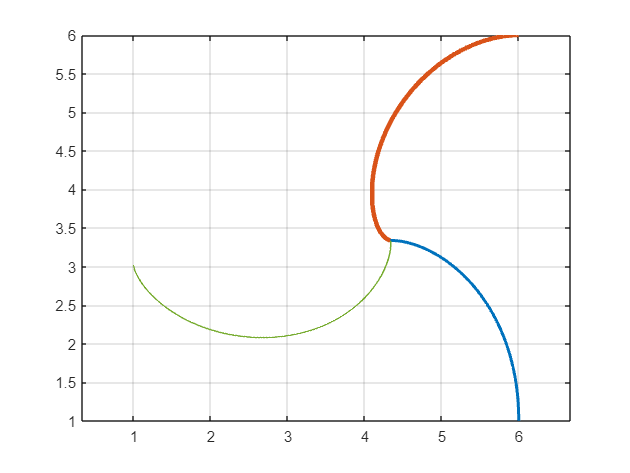

REG_01=sim("Regulation_01.slx", "StopTime","50");

% additional Parameters for figures
REG_01.x_rv = x_d;
REG_01.y_rv = y_d;
REG_01.v_sat = v_sat;
REG_01.w_sat = w_sat;
save("Results/REG_01.mat", "REG_01");

figure
plot(REG_01.x1.signals.values, REG_01.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(REG_01.x2.signals.values, REG_01.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(REG_01.x3.signals.values, REG_01.y3.signals.values, "Color","#77AC30", "LineWidth",1)

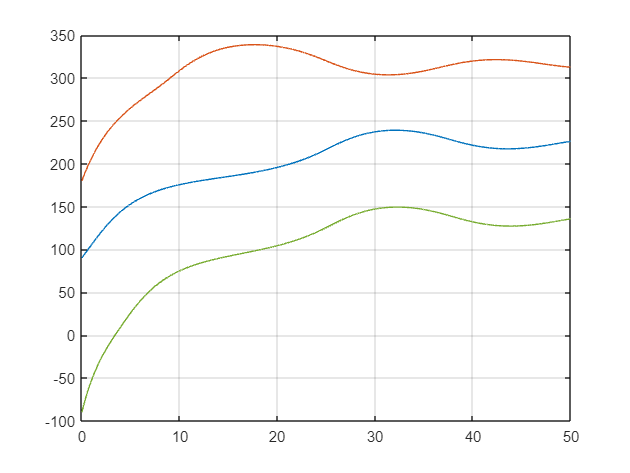

figure
plot(REG_01.theta_rad1.time, REG_01.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(REG_01.theta_rad2.time, REG_01.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(REG_01.theta_rad3.time, REG_01.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

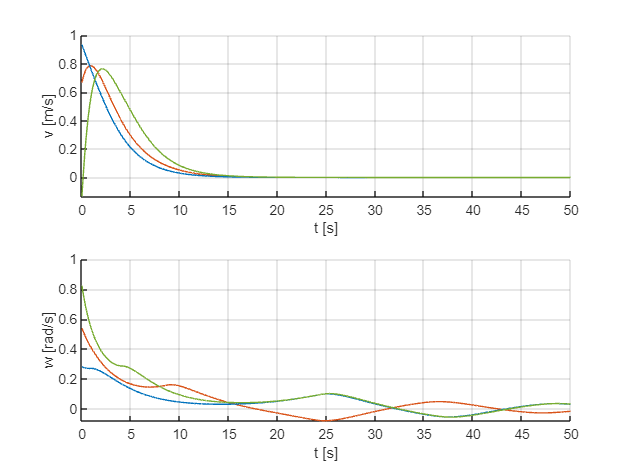

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(REG_01.v1.time, REG_01.v1.signals.values, "Color","#D95319")
plot(REG_01.v2.time, REG_01.v2.signals.values, "Color","#0072BD")
plot(REG_01.v3.time, REG_01.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(REG_01.w1.time, REG_01.w1.signals.values, "Color","#D95319")
plot(REG_01.w2.time, REG_01.w2.signals.values, "Color","#0072BD")
plot(REG_01.w3.time, REG_01.w3.signals.values, "Color","#77AC30")

### Posture Regulation

Posture Regulation initialization

PR_k1=0.7;
PR_k2=1.5;
PR_k3=3; 
tolerance_posture = 1e-2; % variable used for switching/avoid singularity when using posture regulation

x_d=p_fin(1);
y_d=p_fin(2);
theta_d=p_fin(3);
theta_d*rad2deg

ans = 60.0001

Simulating and Plotting Results

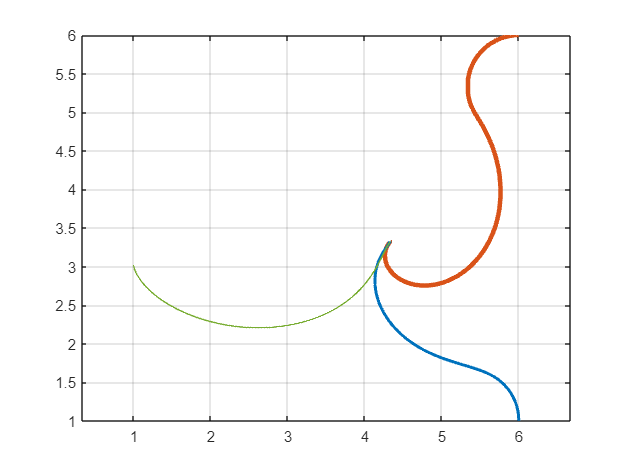

REG_02=sim("Regulation_02.slx", "StopTime","30");

% additional Parameters for figures
REG_02.x_rv = x_d;
REG_02.y_rv = y_d;
REG_02.theta_rv = theta_d;
REG_02.v_sat = v_sat;
REG_02.w_sat = w_sat;
save("Results/REG_02.mat", "REG_02");


figure
plot(REG_02.x1.signals.values, REG_02.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(REG_02.x2.signals.values, REG_02.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(REG_02.x3.signals.values, REG_02.y3.signals.values, "Color","#77AC30", "LineWidth",1)

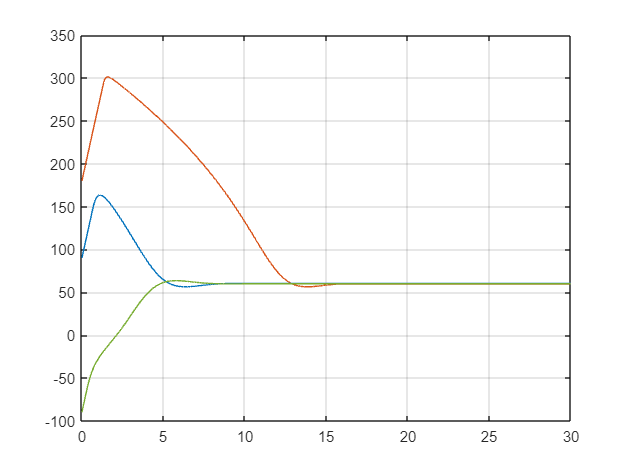

figure
plot(REG_02.theta_rad1.time, REG_02.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(REG_02.theta_rad2.time, REG_02.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(REG_02.theta_rad3.time, REG_02.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

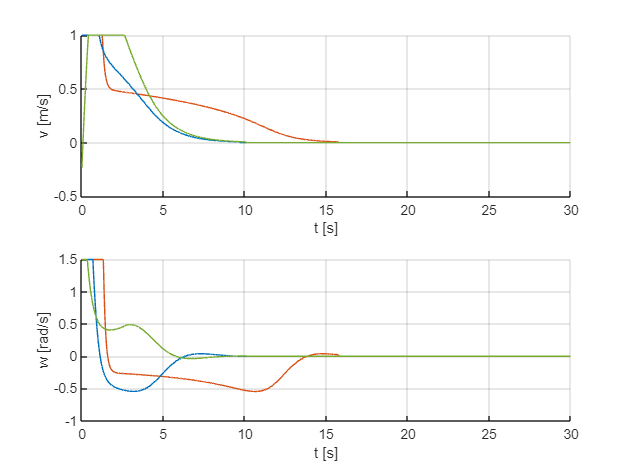

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(REG_02.v1.time, REG_02.v1.signals.values, "Color","#D95319")
plot(REG_02.v2.time, REG_02.v2.signals.values, "Color","#0072BD")
plot(REG_02.v3.time, REG_02.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(REG_02.w1.time, REG_02.w1.signals.values, "Color","#D95319")
plot(REG_02.w2.time, REG_02.w2.signals.values, "Color","#0072BD")
plot(REG_02.w3.time, REG_02.w3.signals.values, "Color","#77AC30")

# *Trajectory Tracking Problem*

In the following sections we will provide the results for the 4 trajectory tracking contollers developed for Phase 3 starting from a the consensus pose defined by one of the 2 controllers developed in Phase 2

#### Trajectory Definition

Circular Trajectory with center in the rendez-vous coordinate

The radius of the circonference must give the robot the space necessary not to hit a wall namely 0.5m. so knowing the center of the circonference we will decide a radius whit values in [1, 2] that respect this conditions r>=1 granted by consensus policy

r=2;
l_min= min([p_fin(1)-2.5, 4.5-p_fin(1), p_fin(2)-2.5, 4.5-p_fin(2)]);
if(l_min < 0)
    r = r+l_min;  
end
r % radius of the circonference

r = 2

w = 0.25; % Angular frequency
ph_1 = 0*deg2rad; % Initial Phase of Unicycle 1
ph_2 = 120*deg2rad; % Initial Phase of Unicycle 2
ph_3 = 240*deg2rad; % Initial Phase of Unicycle 3

% time vector for one revolution
time=0:1e-3:2*pi/w;
time(end+1)=2*pi/w;

% trajectories
x_d1 = p_fin(1)+r*cos(w*time+ph_1);
y_d1 = p_fin(2)+r*sin(w*time+ph_1);
x_d2 = p_fin(1)+r*cos(w*time+ph_2);
y_d2 = p_fin(2)+r*sin(w*time+ph_2);
x_d3 = p_fin(1)+r*cos(w*time+ph_3);
y_d3 = p_fin(2)+r*sin(w*time+ph_3);

% derivative of trajecotries
x_dot1 = -r*sin(w*time+ph_1)*w;
y_dot1 = r*cos(w*time+ph_1)*w;
x_dot2 = -r*sin(w*time+ph_2)*w;
y_dot2 = r*cos(w*time+ph_2)*w;
x_dot3 = -r*sin(w*time+ph_3)*w;
y_dot3 = r*cos(w*time+ph_3)*w;

% second derivative of trajecotries
x_dotdot1 = -r*cos(w*time+ph_1)*(w^2);
y_dotdot1 = -r*sin(w*time+ph_1)*(w^2);
x_dotdot2 = -r*cos(w*time+ph_2)*(w^2);
y_dotdot2 = -r*sin(w*time+ph_2)*(w^2);
x_dotdot3 = -r*cos(w*time+ph_3)*(w^2);
y_dotdot3 = -r*sin(w*time+ph_3)*(w^2);

% Trajectories in terms of the point b for Output Feedback
OF_b = 1;

x_bd1 = x_d1 + OF_b*cos(w*time+ph_1+pi/2);
y_bd1 = y_d1 + OF_b*sin(w*time+ph_1+pi/2);
x_bd2 = x_d2 + OF_b*cos(w*time+ph_2+pi/2);
y_bd2 = y_d2 + OF_b*sin(w*time+ph_2+pi/2);
x_bd3 = x_d3 + OF_b*cos(w*time+ph_3+pi/2);
y_bd3 = y_d3 + OF_b*sin(w*time+ph_3+pi/2);

% Derivatives of the trajectories in terms of the point b for Output Feedback
x_bdot1 = x_dot1 - OF_b*sin(w*time+ph_1+pi/2)*w;
y_bdot1 = y_dot1 + OF_b*cos(w*time+ph_1+pi/2)*w;
x_bdot2 = x_dot2 - OF_b*sin(w*time+ph_2+pi/2)*w;
y_bdot2 = y_dot2 + OF_b*cos(w*time+ph_2+pi/2)*w;
x_bdot3 = x_dot3 - OF_b*sin(w*time+ph_3+pi/2)*w;
y_bdot3 = y_dot3 + OF_b*cos(w*time+ph_3+pi/2)*w;

#### Robot poistion initialization

The position are based on consensus so will be the same independently of the Phase 2 controller and the robot while the orientation will vary depending on the controller used

TT_x_init = p_fin(1);
TT_y_init = p_fin(2);

% with posture regulation the orientation will be the same for all robots
TT_theta_posture = p_fin(3);

% with position regulation the orientation will be diffferent for the robot
% and depends on the simulation done previously
TT_theta_position_1 = REG_01.theta_rad1.signals.values(end);
TT_theta_position_2 = REG_01.theta_rad2.signals.values(end);
TT_theta_position_3 = REG_01.theta_rad3.signals.values(end);

### Output Feedback with Change of Variables

Output Feedback initialization

OF_k1=0.5;
OF_k2=0.5;

Simulating and Plotting Results for Position Regulation

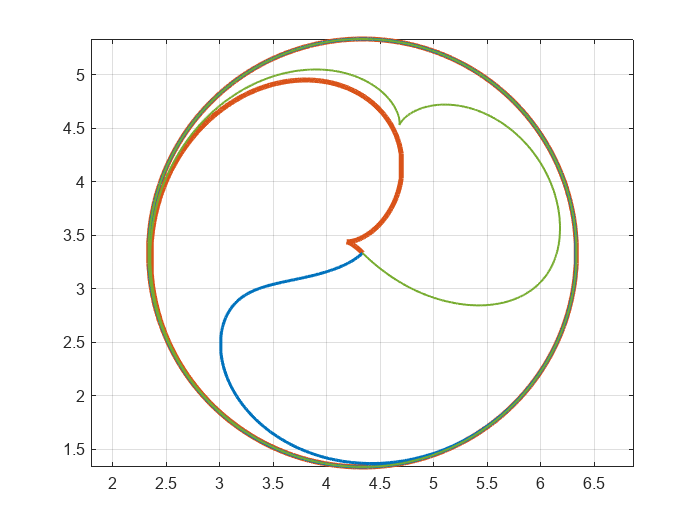

% setting orientation initial conditions
TT_theta1_init = TT_theta_position_1;
TT_theta2_init = TT_theta_position_2;
TT_theta3_init = TT_theta_position_3;

TRK_01_position=sim("Tracking_01.slx", "StopTime","50");

% additional Parameters for figures
TRK_01_position.v_sat = v_sat;
TRK_01_position.w_sat = w_sat;
save("Results/TRK_01_position.mat", "TRK_01_position");

figure
plot(TRK_01_position.x1.signals.values, TRK_01_position.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_01_position.x2.signals.values, TRK_01_position.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_01_position.x3.signals.values, TRK_01_position.y3.signals.values, "Color","#77AC30", "LineWidth",1)

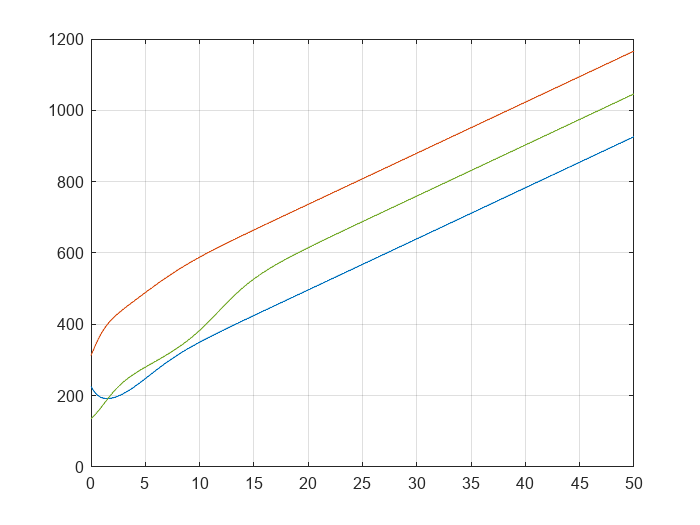

figure
plot(TRK_01_position.theta_rad1.time, TRK_01_position.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_01_position.theta_rad2.time, TRK_01_position.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_01_position.theta_rad3.time, TRK_01_position.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

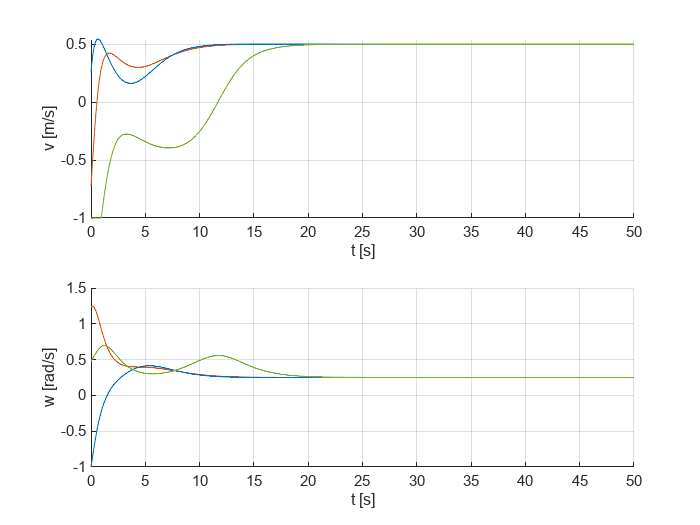

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_01_position.v1.time, TRK_01_position.v1.signals.values, "Color","#D95319")
plot(TRK_01_position.v2.time, TRK_01_position.v2.signals.values, "Color","#0072BD")
plot(TRK_01_position.v3.time, TRK_01_position.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_01_position.w1.time, TRK_01_position.w1.signals.values, "Color","#D95319")
plot(TRK_01_position.w2.time, TRK_01_position.w2.signals.values, "Color","#0072BD")
plot(TRK_01_position.w3.time, TRK_01_position.w3.signals.values, "Color","#77AC30")

Simulating and Plotting Results for Posture Regulation

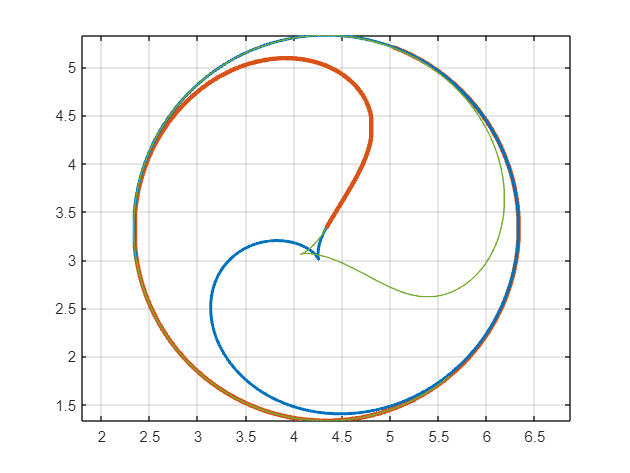

% setting orientation initial conditions
TT_theta1_init = TT_theta_posture;
TT_theta2_init = TT_theta_posture;
TT_theta3_init = TT_theta_posture;

TRK_01_posture=sim("Tracking_01.slx", "StopTime","30");

% additional Parameters for figures
TRK_01_posture.v_sat = v_sat;
TRK_01_posture.w_sat = w_sat;
save("Results/TRK_01_posture.mat", "TRK_01_posture");

figure
plot(TRK_01_posture.x1.signals.values, TRK_01_posture.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_01_posture.x2.signals.values, TRK_01_posture.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_01_posture.x3.signals.values, TRK_01_posture.y3.signals.values, "Color","#77AC30", "LineWidth",1)

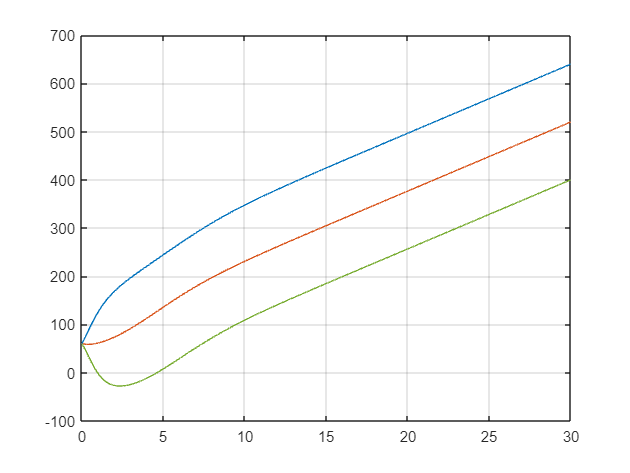

figure
plot(TRK_01_posture.theta_rad1.time, TRK_01_posture.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_01_posture.theta_rad2.time, TRK_01_posture.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_01_posture.theta_rad3.time, TRK_01_posture.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

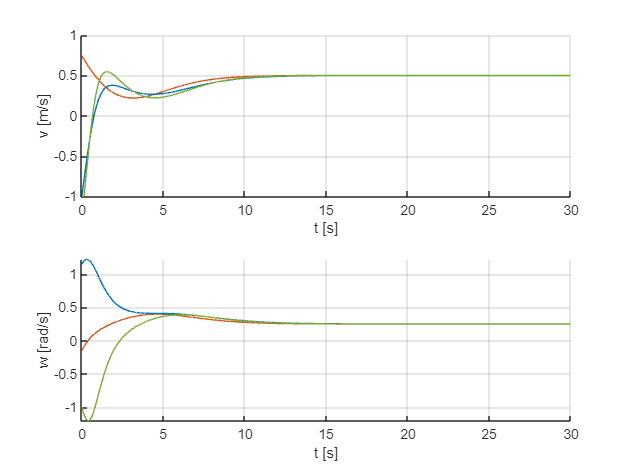

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_01_posture.v1.time, TRK_01_posture.v1.signals.values, "Color","#D95319")
plot(TRK_01_posture.v2.time, TRK_01_posture.v2.signals.values, "Color","#0072BD")
plot(TRK_01_posture.v3.time, TRK_01_posture.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_01_posture.w1.time, TRK_01_posture.w1.signals.values, "Color","#D95319")
plot(TRK_01_posture.w2.time, TRK_01_posture.w2.signals.values, "Color","#0072BD")
plot(TRK_01_posture.w3.time, TRK_01_posture.w3.signals.values, "Color","#77AC30")

### State Feedback with Exact Linearization

State Feedback initialization

SF_b=0.1;
SF_xi1=0.6;
% low gains to guarantee controllers do not exceeed robot specification

Simulating and Plotting Results for Position Regulation

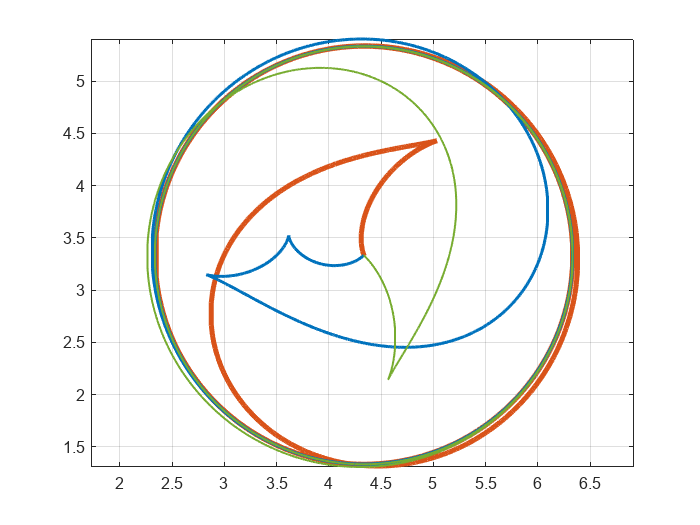

% setting orientation initial conditions
TT_theta1_init = TT_theta_position_1;
TT_theta2_init = TT_theta_position_2;
TT_theta3_init = TT_theta_position_3;

TRK_02_position=sim("Tracking_02.slx", "StopTime","100");

% additional Parameters for figures
TRK_02_position.v_sat = v_sat;
TRK_02_position.w_sat = w_sat;
save("Results/TRK_02_position.mat", "TRK_02_position");

figure
plot(TRK_02_position.x1.signals.values, TRK_02_position.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_02_position.x2.signals.values, TRK_02_position.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_02_position.x3.signals.values, TRK_02_position.y3.signals.values, "Color","#77AC30", "LineWidth",1)

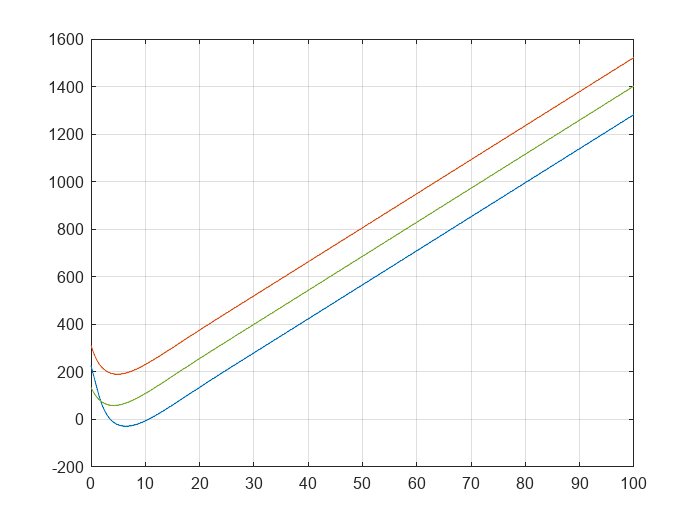

figure
plot(TRK_02_position.theta_rad1.time, TRK_02_position.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_02_position.theta_rad2.time, TRK_02_position.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_02_position.theta_rad3.time, TRK_02_position.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

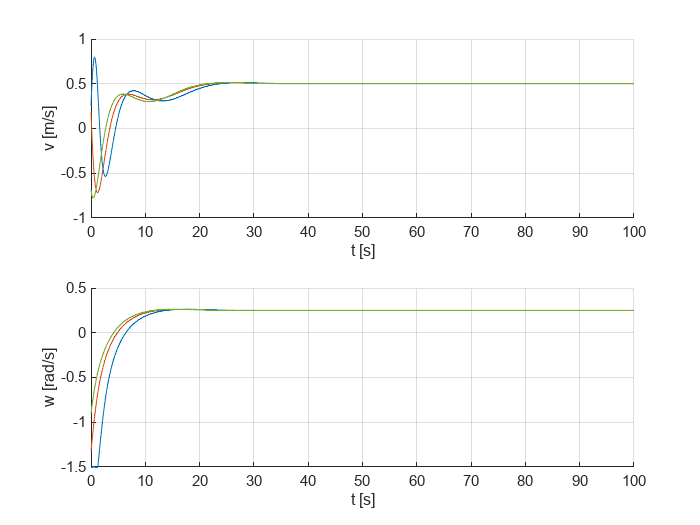

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_02_position.v1.time, TRK_02_position.v1.signals.values, "Color","#D95319")
plot(TRK_02_position.v2.time, TRK_02_position.v2.signals.values, "Color","#0072BD")
plot(TRK_02_position.v3.time, TRK_02_position.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_02_position.w1.time, TRK_02_position.w1.signals.values, "Color","#D95319")
plot(TRK_02_position.w2.time, TRK_02_position.w2.signals.values, "Color","#0072BD")
plot(TRK_02_position.w3.time, TRK_02_position.w3.signals.values, "Color","#77AC30")

Simulating and Plotting Results for Posture Regulation

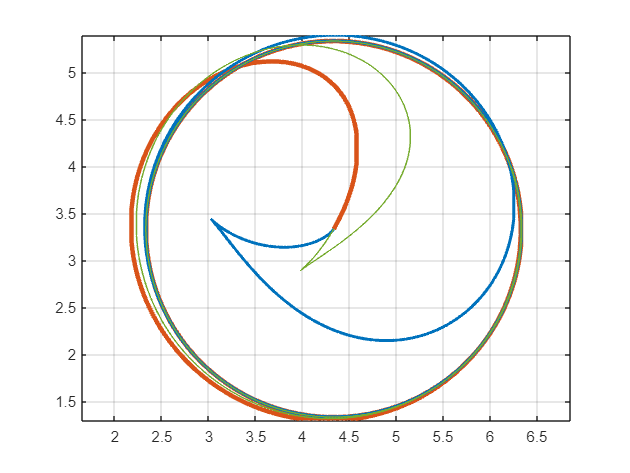

% setting orientation initial conditions
TT_theta1_init = TT_theta_posture;
TT_theta2_init = TT_theta_posture;
TT_theta3_init = TT_theta_posture;

TRK_02_posture=sim("Tracking_02.slx", "StopTime","60");

% additional Parameters for figures
TRK_02_posture.v_sat = v_sat;
TRK_02_posture.w_sat = w_sat;
save("Results/TRK_02_posture.mat", "TRK_02_posture");

figure
plot(TRK_02_posture.x1.signals.values, TRK_02_posture.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_02_posture.x2.signals.values, TRK_02_posture.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_02_posture.x3.signals.values, TRK_02_posture.y3.signals.values, "Color","#77AC30", "LineWidth",1)

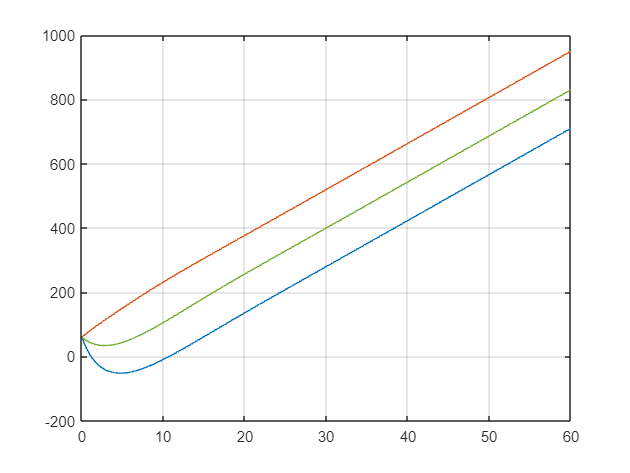

figure
plot(TRK_02_posture.theta_rad1.time, TRK_02_posture.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_02_posture.theta_rad2.time, TRK_02_posture.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_02_posture.theta_rad3.time, TRK_02_posture.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

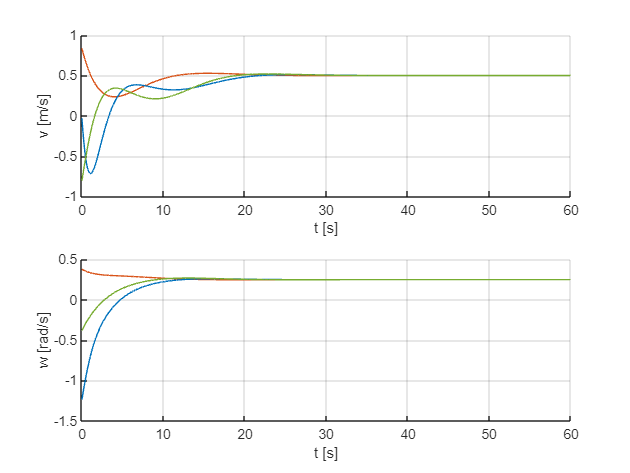

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_02_posture.v1.time, TRK_02_posture.v1.signals.values, "Color","#D95319")
plot(TRK_02_posture.v2.time, TRK_02_posture.v2.signals.values, "Color","#0072BD")
plot(TRK_02_posture.v3.time, TRK_02_posture.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_02_posture.w1.time, TRK_02_posture.w1.signals.values, "Color","#D95319")
plot(TRK_02_posture.w2.time, TRK_02_posture.w2.signals.values, "Color","#0072BD")
plot(TRK_02_posture.w3.time, TRK_02_posture.w3.signals.values, "Color","#77AC30")

### Otuput Feedback with Further Derivatives

Output Feedback initialization

% Define symbolic variables
syms k1 k2 k3 k4 lambda real

% Given matrix A
A_p = [0 0 1 0; 0 0 0 1; -k1 0 -k3 0; 0 -k2 0 -k4];

% Desired eigenvalues
desired_eigenvalues = [-0.5, -0.75, -1, -1.25];

% Characteristic equation
char_eq = det(A_p - lambda*eye(4));

% Set up the system of equations for each desired eigenvalue
eqs = [];
for i = 1:length(desired_eigenvalues)
    eqs = [eqs, subs(char_eq, lambda, desired_eigenvalues(i)) == 0];
end

% Solve the system of equations
sol = solve(eqs, [k1, k2, k3, k4]);

% Display the results
disp('The values for the k coefficients are:')

The values for the k coefficients are:


disp(['k1: ' char(sol.k1)])

k1: [15/16; 1/2; 5/4; 3/4; 5/8; 3/8]


disp(['k2: ' char(sol.k2)])

k2: [1/2; 15/16; 3/8; 5/8; 3/4; 5/4]


disp(['k3: ' char(sol.k3)])

k3: [2; 3/2; 9/4; 7/4; 7/4; 5/4]


disp(['k4: ' char(sol.k4)])

k4: [3/2; 2; 5/4; 7/4; 7/4; 9/4]



OF_k1_FD = 15/16;
OF_k2_FD = 1/2;
OF_k3_FD = 2;
OF_k4_FD = 3/2;
A_p=[0, 0, 1, 0;
   0, 0, 0, 1;
   -OF_k1_FD, 0, -OF_k3_FD, 0;
   0, -OF_k2_FD, 0, -OF_k4_FD];
eigs(A_p)

ans =    -1.2500
   -1.0000
   -0.7500
   -0.5000


Simulating and Plotting Results for Position Regulation

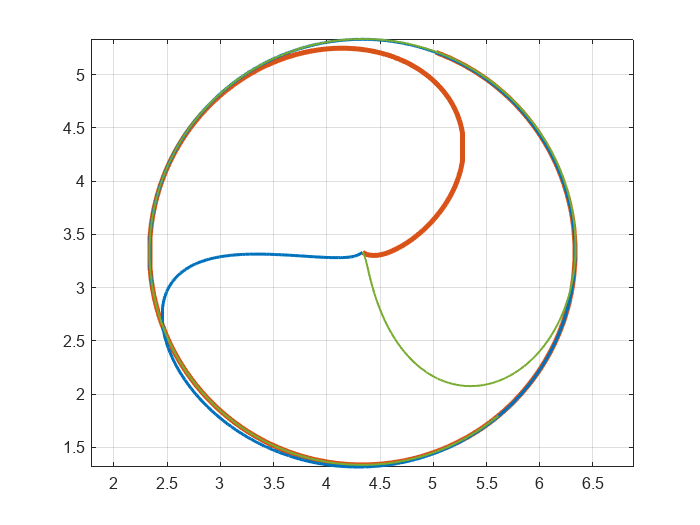

% setting orientation initial conditions
TT_theta1_init = TT_theta_position_1;
TT_theta2_init = TT_theta_position_2;
TT_theta3_init = TT_theta_position_3;

TRK_03_position=sim("Tracking_03.slx", "StopTime","30");

% additional Parameters for figures
TRK_03_position.v_sat = v_sat;
TRK_03_position.w_sat = w_sat;
save("Results/TRK_03_position.mat", "TRK_03_position");

figure
plot(TRK_03_position.x1.signals.values, TRK_03_position.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_03_position.x2.signals.values, TRK_03_position.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_03_position.x3.signals.values, TRK_03_position.y3.signals.values, "Color","#77AC30", "LineWidth",1)

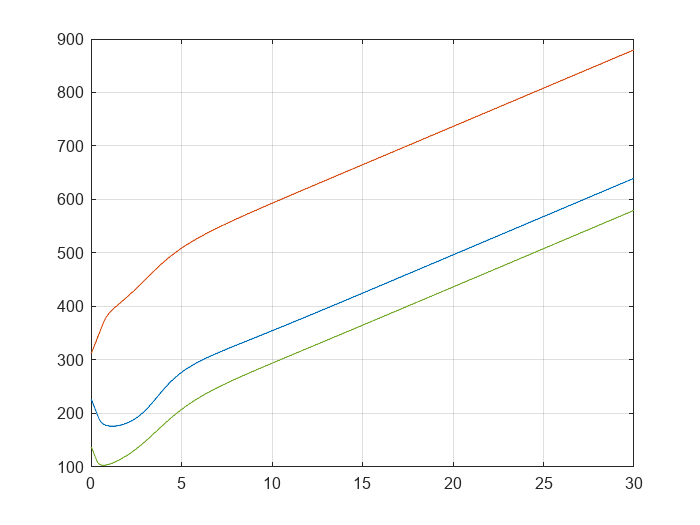

figure
plot(TRK_03_position.theta_rad1.time, TRK_03_position.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_03_position.theta_rad2.time, TRK_03_position.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_03_position.theta_rad3.time, TRK_03_position.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

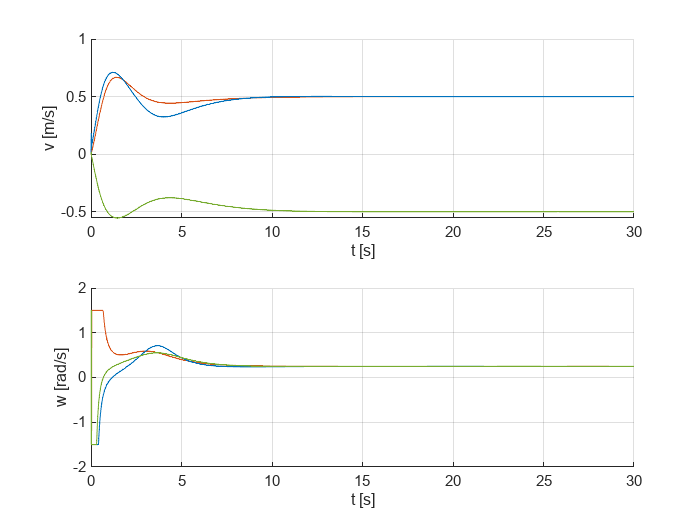

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_03_position.v1.time, TRK_03_position.v1.signals.values, "Color","#D95319")
plot(TRK_03_position.v2.time, TRK_03_position.v2.signals.values, "Color","#0072BD")
plot(TRK_03_position.v3.time, TRK_03_position.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_03_position.w1.time, TRK_03_position.w1.signals.values, "Color","#D95319")
plot(TRK_03_position.w2.time, TRK_03_position.w2.signals.values, "Color","#0072BD")
plot(TRK_03_position.w3.time, TRK_03_position.w3.signals.values, "Color","#77AC30")

Simulating and Plotting Results for Posture Regulation

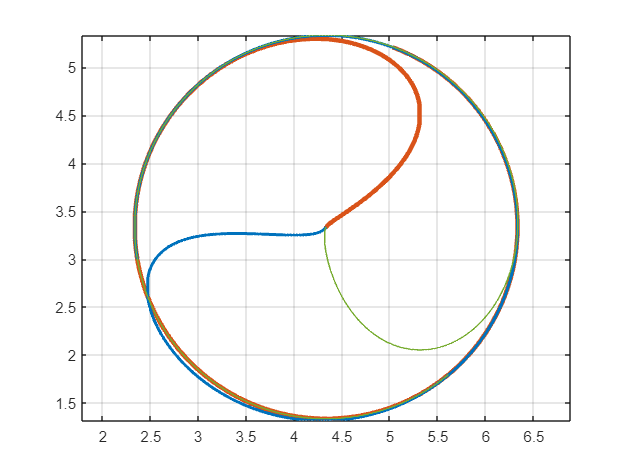

% setting orientation initial conditions
TT_theta1_init = TT_theta_posture;
TT_theta2_init = TT_theta_posture;
TT_theta3_init = TT_theta_posture;

TRK_03_posture=sim("Tracking_03.slx", "StopTime","30");

% additional Parameters for figures
TRK_03_posture.v_sat = v_sat;
TRK_03_posture.w_sat = w_sat;
save("Results/TRK_03_posture.mat", "TRK_03_posture");

figure
plot(TRK_03_posture.x1.signals.values, TRK_03_posture.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_03_posture.x2.signals.values, TRK_03_posture.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_03_posture.x3.signals.values, TRK_03_posture.y3.signals.values, "Color","#77AC30", "LineWidth",1)

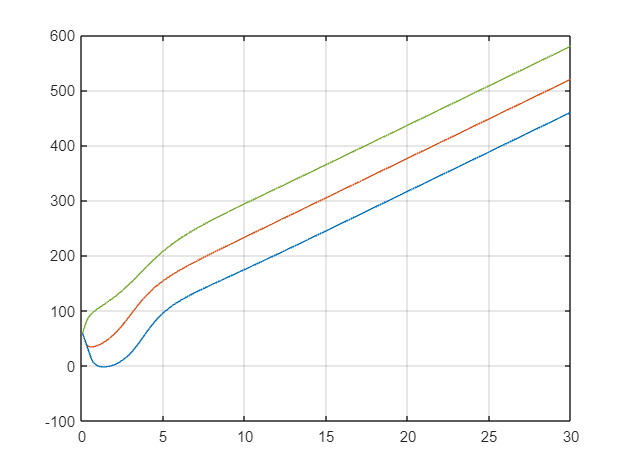

figure
plot(TRK_03_posture.theta_rad1.time, TRK_03_posture.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_03_posture.theta_rad2.time, TRK_03_posture.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_03_posture.theta_rad3.time, TRK_03_posture.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

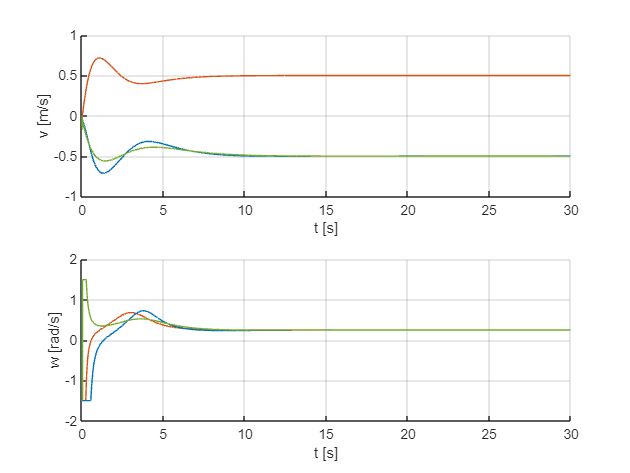

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_03_posture.v1.time, TRK_03_posture.v1.signals.values, "Color","#D95319")
plot(TRK_03_posture.v2.time, TRK_03_posture.v2.signals.values, "Color","#0072BD")
plot(TRK_03_posture.v3.time, TRK_03_posture.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_03_posture.w1.time, TRK_03_posture.w1.signals.values, "Color","#D95319")
plot(TRK_03_posture.w2.time, TRK_03_posture.w2.signals.values, "Color","#0072BD")
plot(TRK_03_posture.w3.time, TRK_03_posture.w3.signals.values, "Color","#77AC30")

### State Feedback with Approximate Linearization

State Feedback initialization

SF_a = 10;
SF_xi2 = 0.005;

Simulating and Plotting Results for Position Regulation

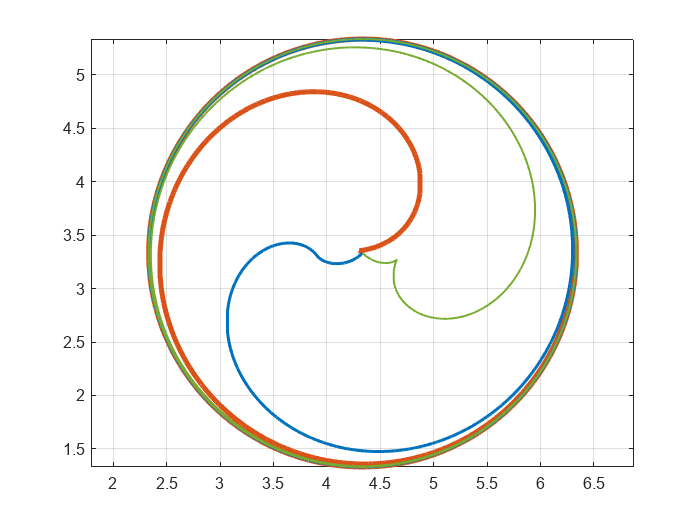

% setting orientation initial conditions
TT_theta1_init = TT_theta_position_1;
TT_theta2_init = TT_theta_position_2;
TT_theta3_init = TT_theta_position_3;

TRK_04_position=sim("Tracking_04.slx", "StopTime","60");

% additional Parameters for figures
TRK_04_position.v_sat = v_sat;
TRK_04_position.w_sat = w_sat;
save("Results/TRK_04_position.mat", "TRK_04_position");

figure
plot(TRK_04_position.x1.signals.values, TRK_04_position.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_04_position.x2.signals.values, TRK_04_position.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_04_position.x3.signals.values, TRK_04_position.y3.signals.values, "Color","#77AC30", "LineWidth",1)

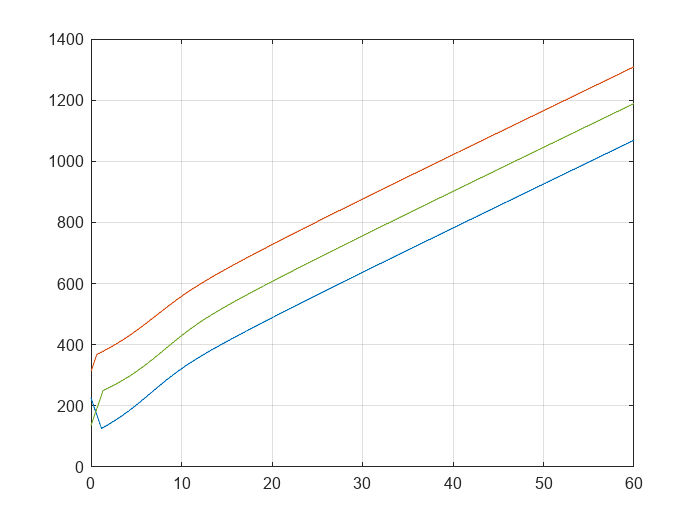

figure
plot(TRK_04_position.theta_rad1.time, TRK_04_position.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_04_position.theta_rad2.time, TRK_04_position.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_04_position.theta_rad3.time, TRK_04_position.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

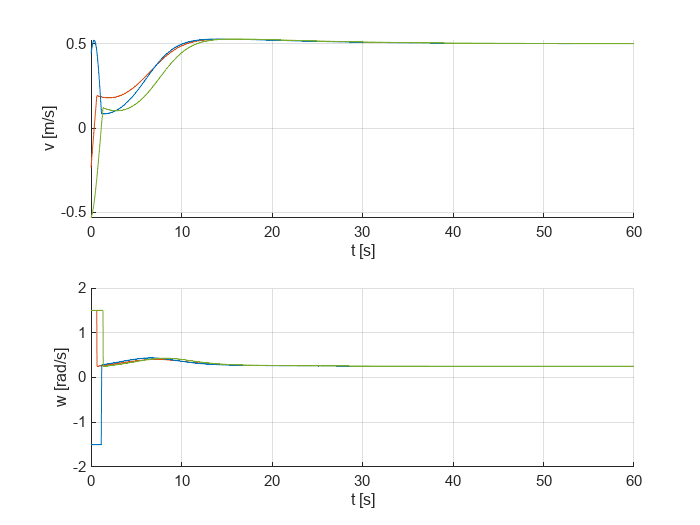

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_04_position.v1.time, TRK_04_position.v1.signals.values, "Color","#D95319")
plot(TRK_04_position.v2.time, TRK_04_position.v2.signals.values, "Color","#0072BD")
plot(TRK_04_position.v3.time, TRK_04_position.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_04_position.w1.time, TRK_04_position.w1.signals.values, "Color","#D95319")
plot(TRK_04_position.w2.time, TRK_04_position.w2.signals.values, "Color","#0072BD")
plot(TRK_04_position.w3.time, TRK_04_position.w3.signals.values, "Color","#77AC30")

Simulating and Plotting Results for Posture Regulation

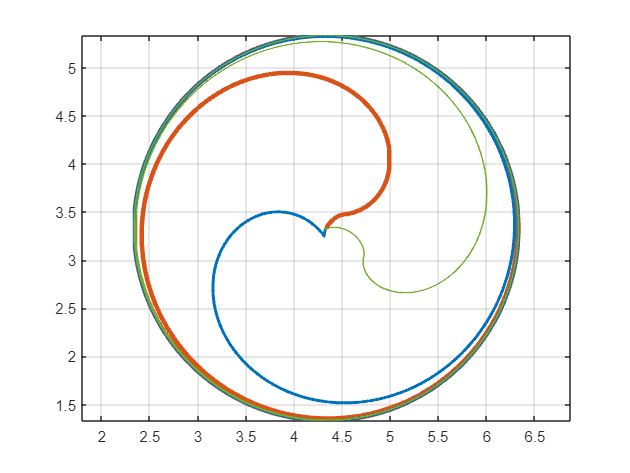

% setting orientation initial conditions
TT_theta1_init = TT_theta_posture;
TT_theta2_init = TT_theta_posture;
TT_theta3_init = TT_theta_posture;

TRK_04_posture=sim("Tracking_04.slx", "StopTime","60");

% additional Parameters for figures
TRK_04_posture.v_sat = v_sat;
TRK_04_posture.w_sat = w_sat;
save("Results/TRK_04_posture.mat", "TRK_04_posture");

figure
plot(TRK_04_posture.x1.signals.values, TRK_04_posture.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(TRK_04_posture.x2.signals.values, TRK_04_posture.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(TRK_04_posture.x3.signals.values, TRK_04_posture.y3.signals.values, "Color","#77AC30", "LineWidth",1)

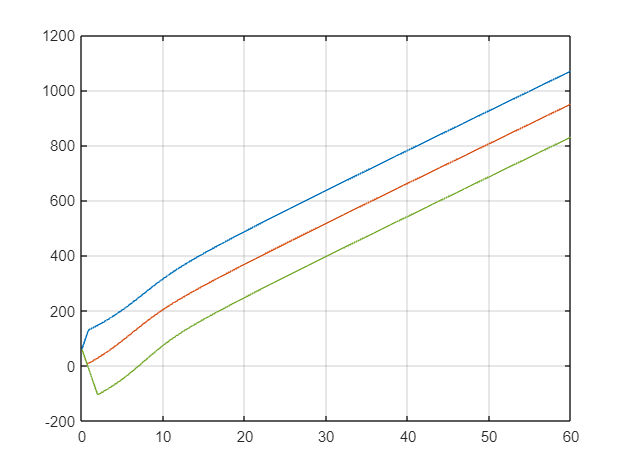

figure
plot(TRK_04_posture.theta_rad1.time, TRK_04_posture.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(TRK_04_posture.theta_rad2.time, TRK_04_posture.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(TRK_04_posture.theta_rad3.time, TRK_04_posture.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

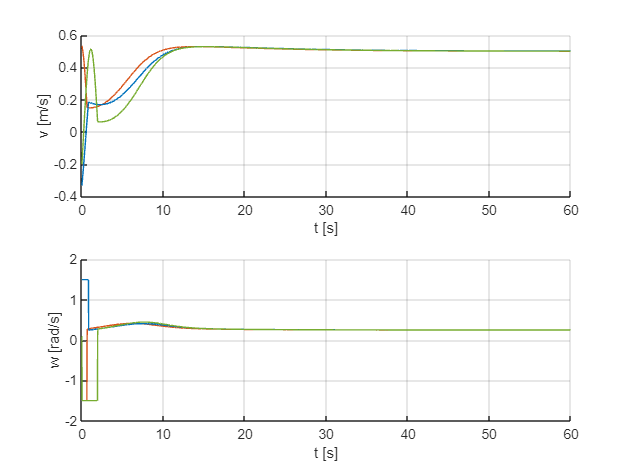

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(TRK_04_posture.v1.time, TRK_04_posture.v1.signals.values, "Color","#D95319")
plot(TRK_04_posture.v2.time, TRK_04_posture.v2.signals.values, "Color","#0072BD")
plot(TRK_04_posture.v3.time, TRK_04_posture.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(TRK_04_posture.w1.time, TRK_04_posture.w1.signals.values, "Color","#D95319")
plot(TRK_04_posture.w2.time, TRK_04_posture.w2.signals.values, "Color","#0072BD")
plot(TRK_04_posture.w3.time, TRK_04_posture.w3.signals.values, "Color","#77AC30")

# ***Switching Controllers***

The following sections will show the switching controller developed by combining the 2 regulations controller with the 4 trajecotry tracking controllers

## Switching Controller 1: Position Regulation and Output Feedback with Change of Variables

Simulating and Plotting Results

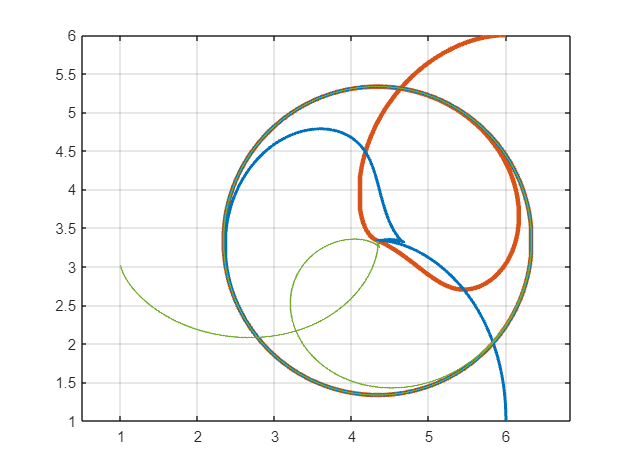

SW_01=sim("Switching_01.slx", "StopTime","60");

% additional Parameters for figures
SW_01.x_rv = x_d;
SW_01.y_rv = y_d;
SW_01.v_sat = v_sat;
SW_01.w_sat = w_sat;
save("Results/SW_01.mat", "SW_01");

figure
plot(SW_01.x1.signals.values, SW_01.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_01.x2.signals.values, SW_01.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_01.x3.signals.values, SW_01.y3.signals.values, "Color","#77AC30", "LineWidth",1)

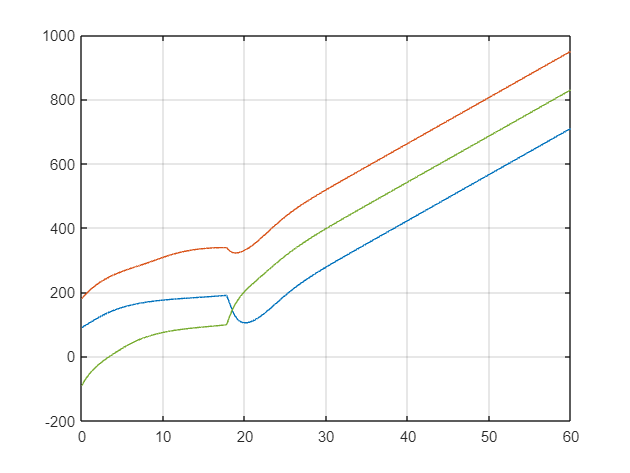

figure
plot(SW_01.theta_rad1.time, SW_01.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_01.theta_rad2.time, SW_01.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_01.theta_rad3.time, SW_01.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

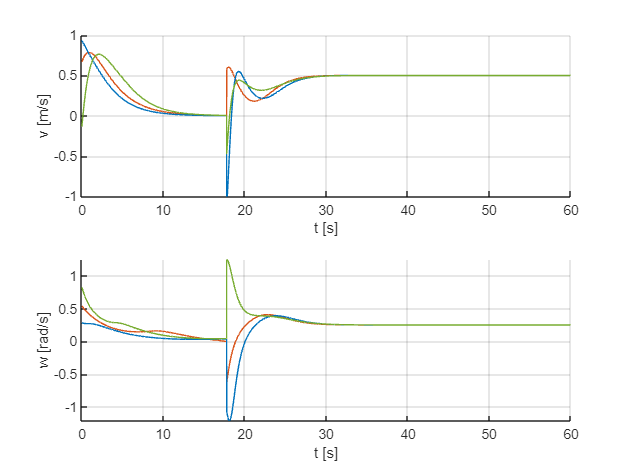

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_01.v1.time, SW_01.v1.signals.values, "Color","#D95319")
plot(SW_01.v2.time, SW_01.v2.signals.values, "Color","#0072BD")
plot(SW_01.v3.time, SW_01.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_01.w1.time, SW_01.w1.signals.values, "Color","#D95319")
plot(SW_01.w2.time, SW_01.w2.signals.values, "Color","#0072BD")
plot(SW_01.w3.time, SW_01.w3.signals.values, "Color","#77AC30")

## Switching Controller 2: Position Regulation and State Feedback with Exact Linearization

Simulating and Plotting Results

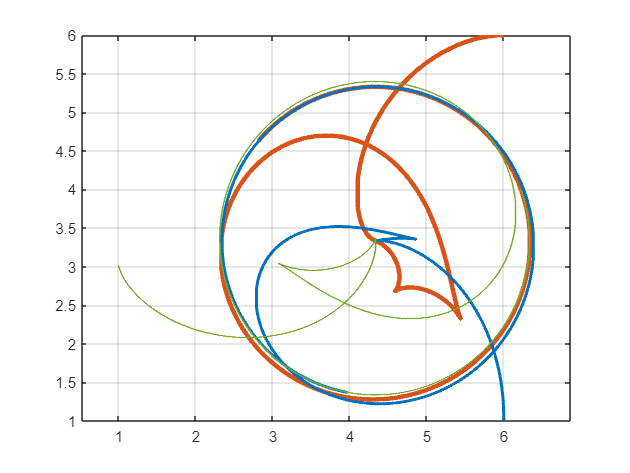

SW_02=sim("Switching_02.slx", "StopTime","60");

% additional Parameters for figures
SW_02.x_rv = x_d;
SW_02.y_rv = y_d;
SW_02.v_sat = v_sat;
SW_02.w_sat = w_sat;
save("Results/SW_02.mat", "SW_02");

figure
plot(SW_02.x1.signals.values, SW_02.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_02.x2.signals.values, SW_02.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_02.x3.signals.values, SW_02.y3.signals.values, "Color","#77AC30", "LineWidth",1)

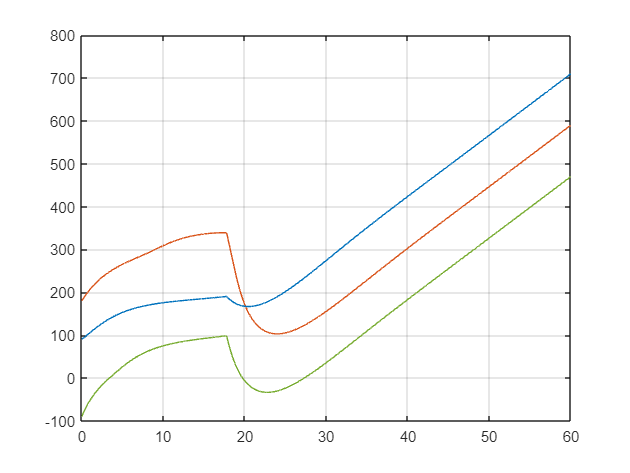

figure
plot(SW_02.theta_rad1.time, SW_02.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_02.theta_rad2.time, SW_02.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_02.theta_rad3.time, SW_02.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

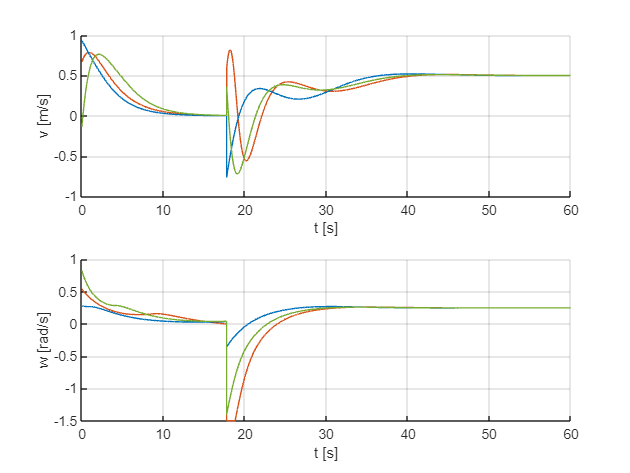

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_02.v1.time, SW_02.v1.signals.values, "Color","#D95319")
plot(SW_02.v2.time, SW_02.v2.signals.values, "Color","#0072BD")
plot(SW_02.v3.time, SW_02.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_02.w1.time, SW_02.w1.signals.values, "Color","#D95319")
plot(SW_02.w2.time, SW_02.w2.signals.values, "Color","#0072BD")
plot(SW_02.w3.time, SW_02.w3.signals.values, "Color","#77AC30")

## Switching Controller 3: Position Regulation and Otuput Feedback with Further Derivatives

Simulating and Plotting Results

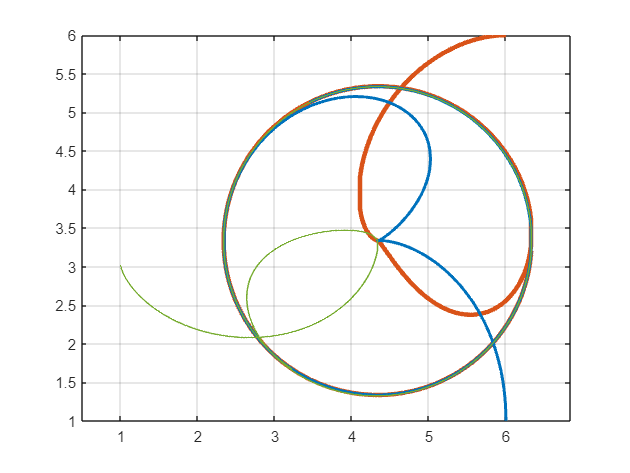

SW_03=sim("Switching_03.slx", "StopTime","50");

% additional Parameters for figures
SW_03.x_rv = x_d;
SW_03.y_rv = y_d;
SW_03.v_sat = v_sat;
SW_03.w_sat = w_sat;
save("Results/SW_03.mat", "SW_03");

figure
plot(SW_03.x1.signals.values, SW_03.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_03.x2.signals.values, SW_03.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_03.x3.signals.values, SW_03.y3.signals.values, "Color","#77AC30", "LineWidth",1)

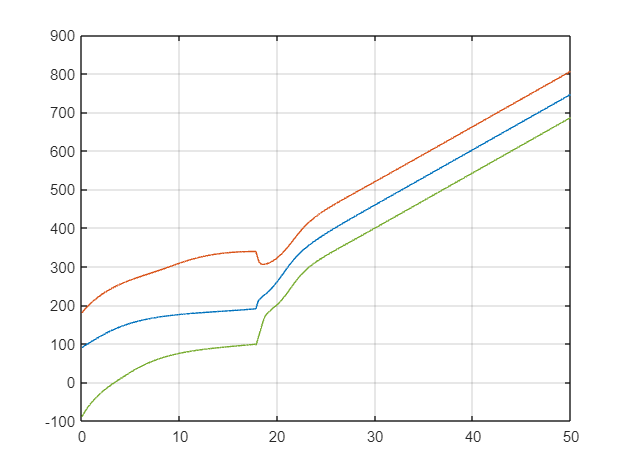

figure
plot(SW_03.theta_rad1.time, SW_03.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_03.theta_rad2.time, SW_03.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_03.theta_rad3.time, SW_03.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

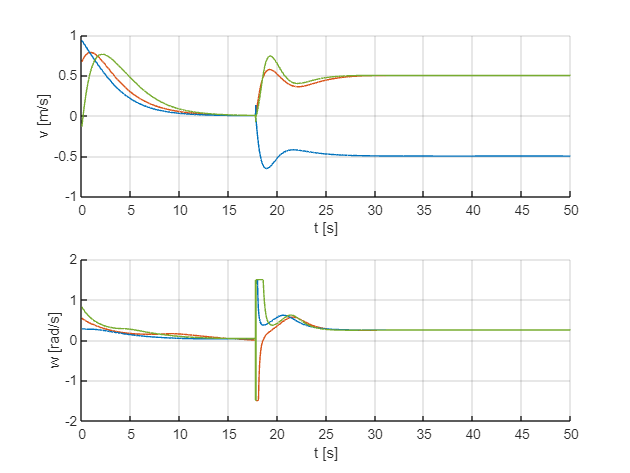

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_03.v1.time, SW_03.v1.signals.values, "Color","#D95319")
plot(SW_03.v2.time, SW_03.v2.signals.values, "Color","#0072BD")
plot(SW_03.v3.time, SW_03.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_03.w1.time, SW_03.w1.signals.values, "Color","#D95319")
plot(SW_03.w2.time, SW_03.w2.signals.values, "Color","#0072BD")
plot(SW_03.w3.time, SW_03.w3.signals.values, "Color","#77AC30")

## Switching Controller 4: Position Regulation and State Feedback with Approximate Linearization

Simulating and Plotting Results

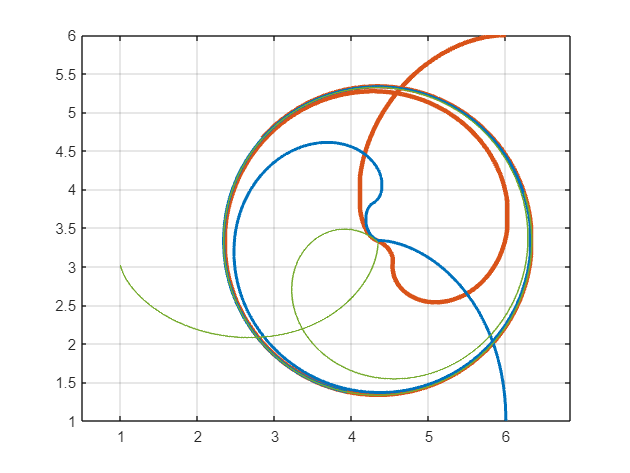

SW_04=sim("Switching_04.slx", "StopTime","60");

% additional Parameters for figures
SW_04.x_rv = x_d;
SW_04.y_rv = y_d;
SW_04.v_sat = v_sat;
SW_04.w_sat = w_sat;
save("Results/SW_04.mat", "SW_04");

figure
plot(SW_04.x1.signals.values, SW_04.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_04.x2.signals.values, SW_04.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_04.x3.signals.values, SW_04.y3.signals.values, "Color","#77AC30", "LineWidth",1)

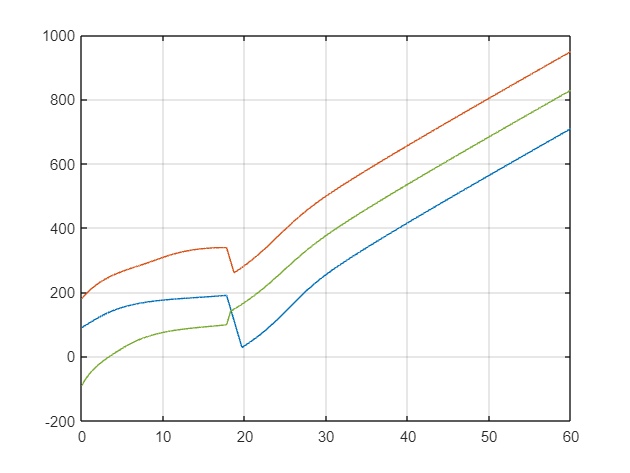

figure
plot(SW_04.theta_rad1.time, SW_04.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_04.theta_rad2.time, SW_04.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_04.theta_rad3.time, SW_04.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

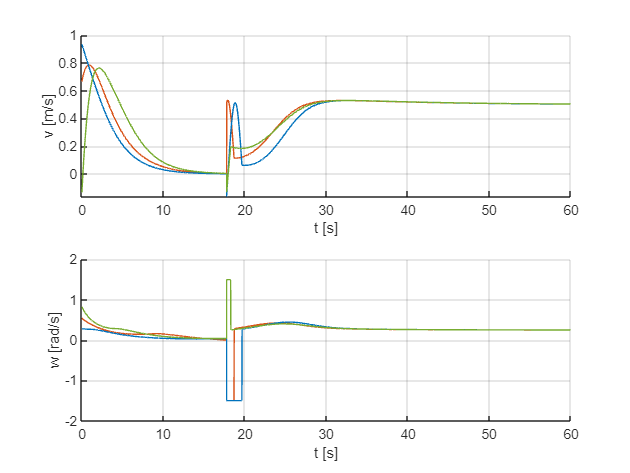

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_04.v1.time, SW_04.v1.signals.values, "Color","#D95319")
plot(SW_04.v2.time, SW_04.v2.signals.values, "Color","#0072BD")
plot(SW_04.v3.time, SW_04.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_04.w1.time, SW_04.w1.signals.values, "Color","#D95319")
plot(SW_04.w2.time, SW_04.w2.signals.values, "Color","#0072BD")
plot(SW_04.w3.time, SW_04.w3.signals.values, "Color","#77AC30")

## Switching Controller 5: Posture Regulation and Output Feedback with Change of Variables

Simulating and Plotting Results

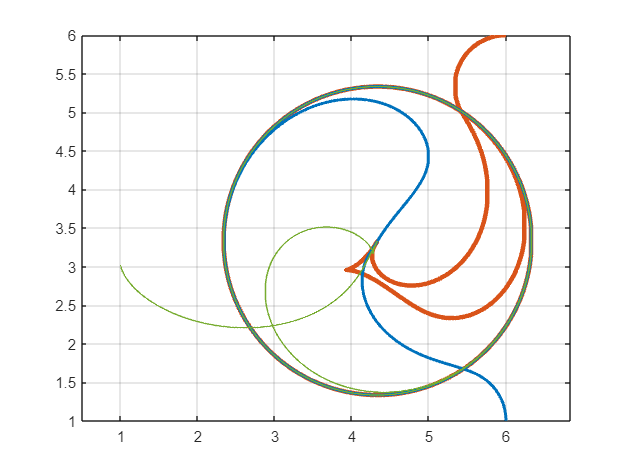

SW_05=sim("Switching_05.slx", "StopTime","80");

% additional Parameters for figures
SW_05.x_rv = x_d;
SW_05.y_rv = y_d;
SW_05.theta_rv = theta_d;
SW_05.v_sat = v_sat;
SW_05.w_sat = w_sat;
save("Results/SW_05.mat", "SW_05");

figure
plot(SW_05.x1.signals.values, SW_05.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_05.x2.signals.values, SW_05.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_05.x3.signals.values, SW_05.y3.signals.values, "Color","#77AC30", "LineWidth",1)

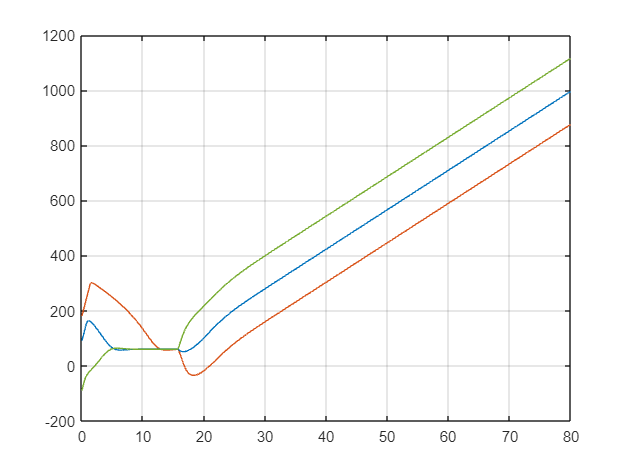

figure
plot(SW_05.theta_rad1.time, SW_05.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_05.theta_rad2.time, SW_05.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_05.theta_rad3.time, SW_05.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

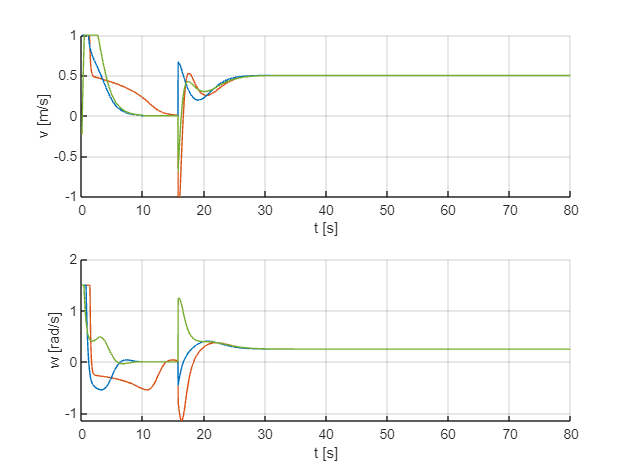

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_05.v1.time, SW_05.v1.signals.values, "Color","#D95319")
plot(SW_05.v2.time, SW_05.v2.signals.values, "Color","#0072BD")
plot(SW_05.v3.time, SW_05.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_05.w1.time, SW_05.w1.signals.values, "Color","#D95319")
plot(SW_05.w2.time, SW_05.w2.signals.values, "Color","#0072BD")
plot(SW_05.w3.time, SW_05.w3.signals.values, "Color","#77AC30")

## Switching Controller 6: Psoture Regulation and State Feedback with Exact Linearization

Simulating and Plotting Results

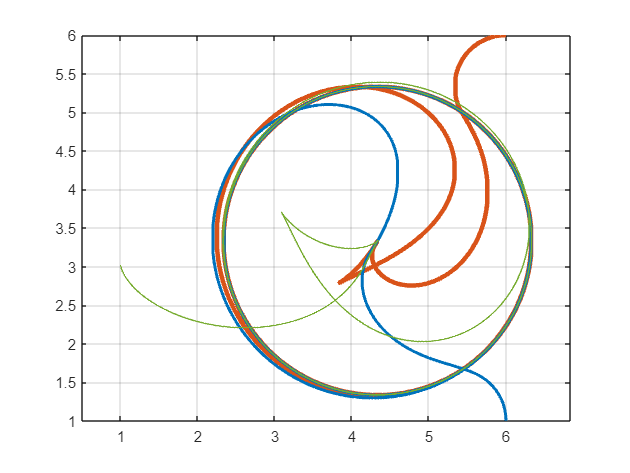

SW_06=sim("Switching_06.slx", "StopTime","80");

% additional Parameters for figures
SW_06.x_rv = x_d;
SW_06.y_rv = y_d;
SW_06.theta_rv = theta_d;
SW_06.v_sat = v_sat;
SW_06.w_sat = w_sat;
save("Results/SW_06.mat", "SW_06");

figure
plot(SW_06.x1.signals.values, SW_06.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_06.x2.signals.values, SW_06.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_06.x3.signals.values, SW_06.y3.signals.values, "Color","#77AC30", "LineWidth",1)

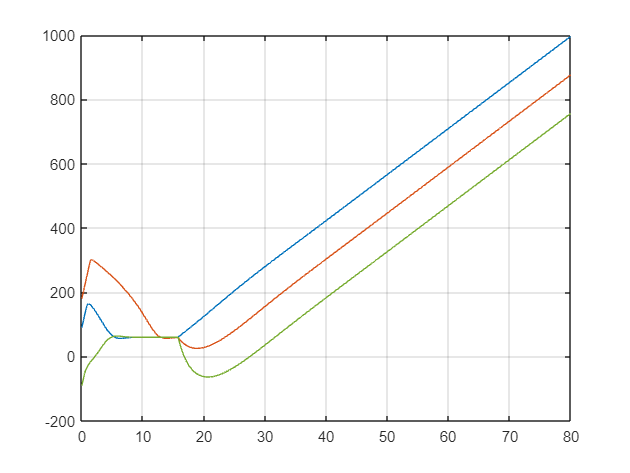

figure
plot(SW_06.theta_rad1.time, SW_06.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_06.theta_rad2.time, SW_06.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_06.theta_rad3.time, SW_06.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

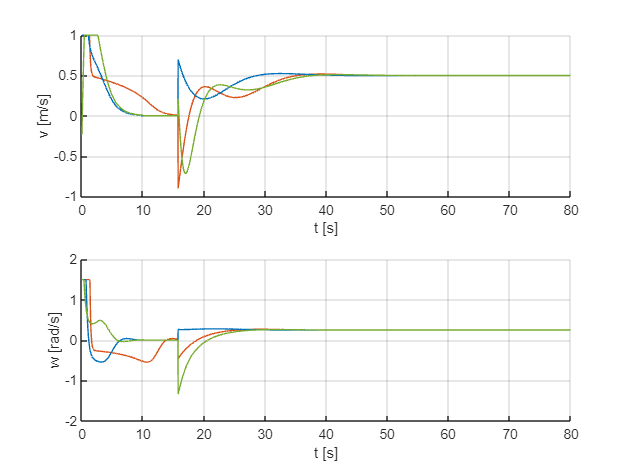

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_06.v1.time, SW_06.v1.signals.values, "Color","#D95319")
plot(SW_06.v2.time, SW_06.v2.signals.values, "Color","#0072BD")
plot(SW_06.v3.time, SW_06.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_06.w1.time, SW_06.w1.signals.values, "Color","#D95319")
plot(SW_06.w2.time, SW_06.w2.signals.values, "Color","#0072BD")
plot(SW_06.w3.time, SW_06.w3.signals.values, "Color","#77AC30")

## Switching Controller 7: Posture Regulation and Otuput Feedback with Further Derivatives

Simulating and Plotting Results

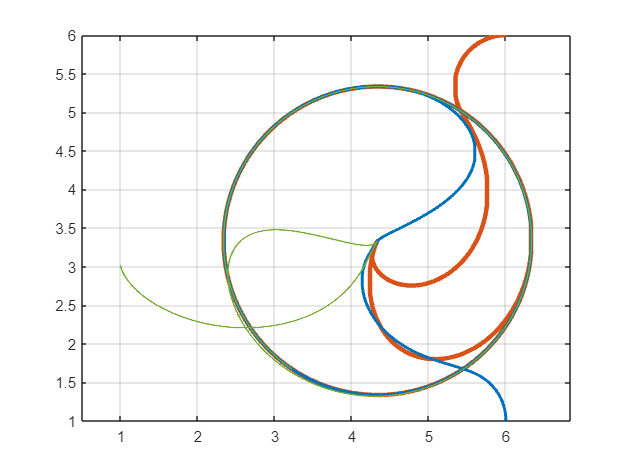

SW_07=sim("Switching_07.slx", "StopTime","50");

% additional Parameters for figures
SW_07.x_rv = x_d;
SW_07.y_rv = y_d;
SW_07.theta_rv = theta_d;
SW_07.v_sat = v_sat;
SW_07.w_sat = w_sat;
save("Results/SW_07.mat", "SW_07");

figure
plot(SW_07.x1.signals.values, SW_07.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_07.x2.signals.values, SW_07.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_07.x3.signals.values, SW_07.y3.signals.values, "Color","#77AC30", "LineWidth",1)

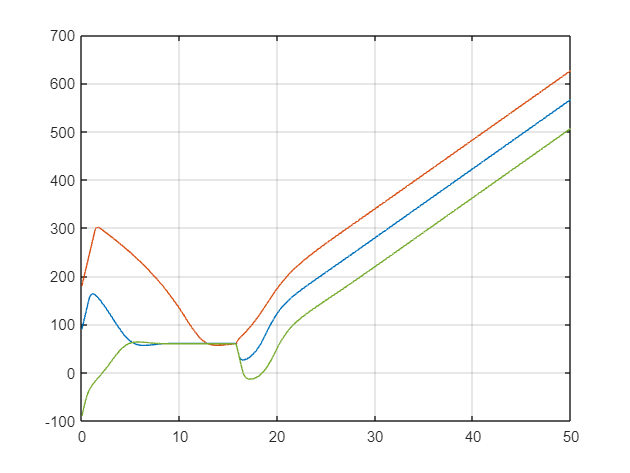

figure
plot(SW_07.theta_rad1.time, SW_07.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_07.theta_rad2.time, SW_07.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_07.theta_rad3.time, SW_07.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

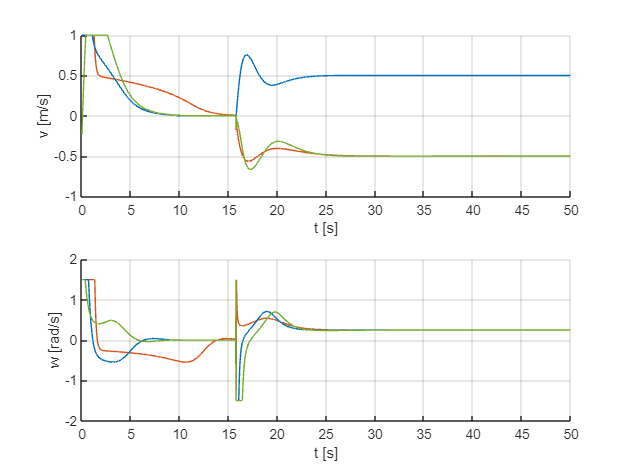

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_07.v1.time, SW_07.v1.signals.values, "Color","#D95319")
plot(SW_07.v2.time, SW_07.v2.signals.values, "Color","#0072BD")
plot(SW_07.v3.time, SW_07.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_07.w1.time, SW_07.w1.signals.values, "Color","#D95319")
plot(SW_07.w2.time, SW_07.w2.signals.values, "Color","#0072BD")
plot(SW_07.w3.time, SW_07.w3.signals.values, "Color","#77AC30")

## Switching Controller 8: Posture Regulation and State Feedback with Approximate Linearization

Simulating and Plotting Results

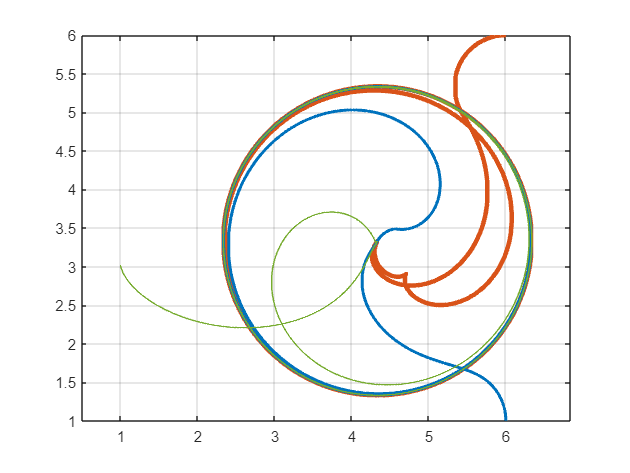

SW_08=sim("Switching_08.slx", "StopTime","150");

% additional Parameters for figures
SW_08.x_rv = x_d;
SW_08.y_rv = y_d;
SW_08.theta_rv = theta_d;
SW_08.v_sat = v_sat;
SW_08.w_sat = w_sat;
save("Results/SW_08.mat", "SW_08");

figure
plot(SW_08.x1.signals.values, SW_08.y1.signals.values, "Color","#D95319", "LineWidth",3)
hold on;
grid on;
axis equal
plot(SW_08.x2.signals.values, SW_08.y2.signals.values, "Color","#0072BD", "LineWidth",2)
plot(SW_08.x3.signals.values, SW_08.y3.signals.values, "Color","#77AC30", "LineWidth",1)

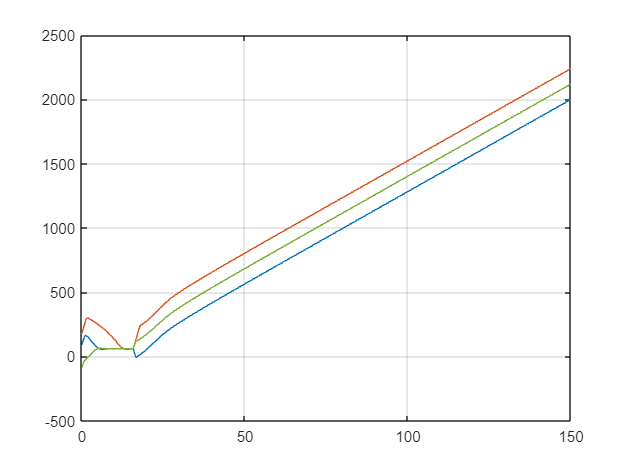

figure
plot(SW_08.theta_rad1.time, SW_08.theta_rad1.signals.values*rad2deg, "Color","#D95319")
grid on;
hold on;
plot(SW_08.theta_rad2.time, SW_08.theta_rad2.signals.values*rad2deg, "Color","#0072BD")
plot(SW_08.theta_rad3.time, SW_08.theta_rad3.signals.values*rad2deg, "Color","#77AC30")

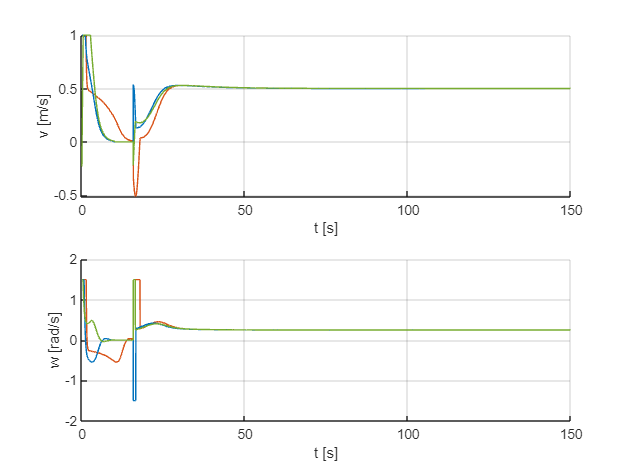

figure

subplot(2,1,1)
xlabel 't [s]'
ylabel 'v [m/s]'
grid on 
hold on
plot(SW_08.v1.time, SW_08.v1.signals.values, "Color","#D95319")
plot(SW_08.v2.time, SW_08.v2.signals.values, "Color","#0072BD")
plot(SW_08.v3.time, SW_08.v3.signals.values, "Color","#77AC30")

subplot(2,1,2)
xlabel 't [s]'
ylabel 'w [rad/s]'
grid on 
hold on
plot(SW_08.w1.time, SW_08.w1.signals.values, "Color","#D95319")
plot(SW_08.w2.time, SW_08.w2.signals.values, "Color","#0072BD")
plot(SW_08.w3.time, SW_08.w3.signals.values, "Color","#77AC30")